% 读取图像
img = imread('./image_correation/A4.jpg');

dpi = 100; % 10像素/厘米
width_cm = 21;  % A4纸宽度
height_cm = 29.7; % A4纸高度
corners = manual_select_corners(img);
% 执行校正
corrected_img = a4_correction(img, corners,dpi,width_cm,height_cm);

校正后图像尺寸: 2100 x 2970
单应性矩阵H:
   1.0e+03 *

    0.0008   -0.0003    1.3259
    0.0000    0.0003    0.6981
    0.0000   -0.0000    0.0010

原始图像尺寸: 4096 x 3072
成功填充像素: 6237000 / 6237000 (100.0%)


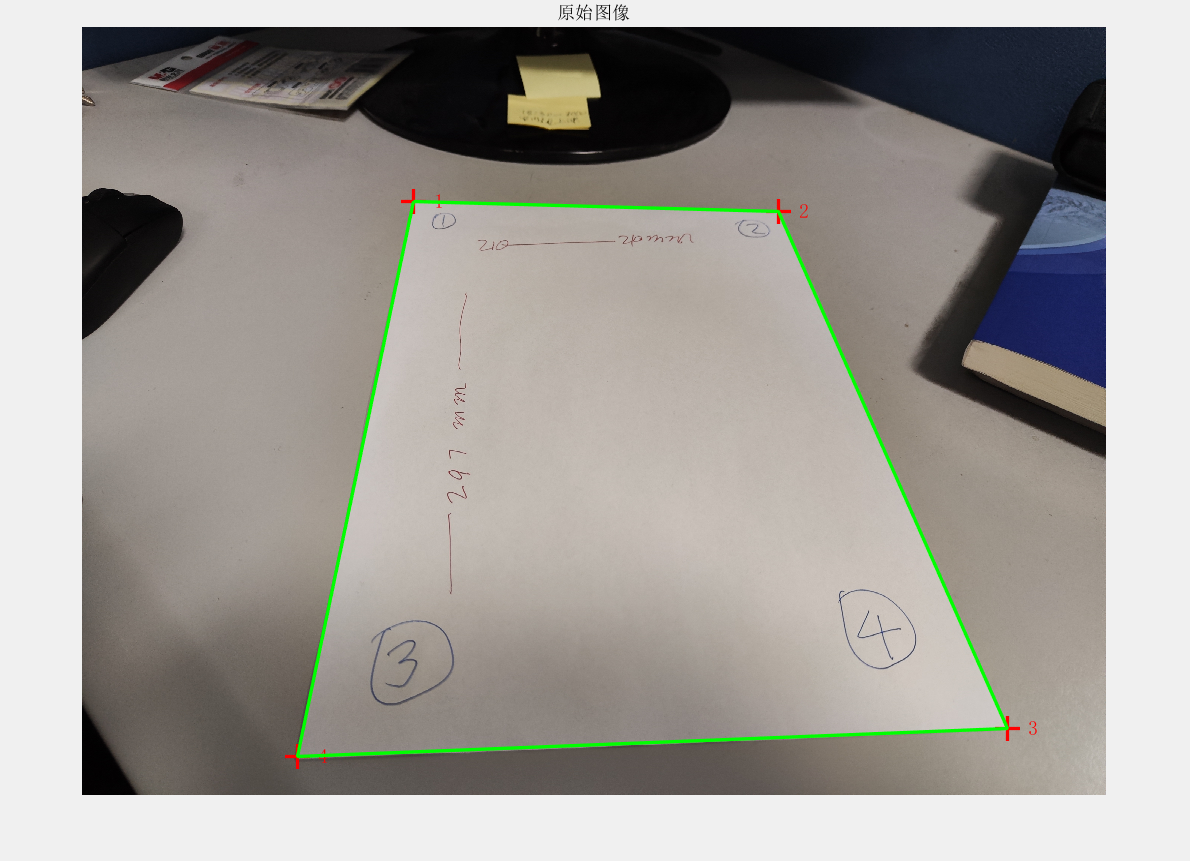

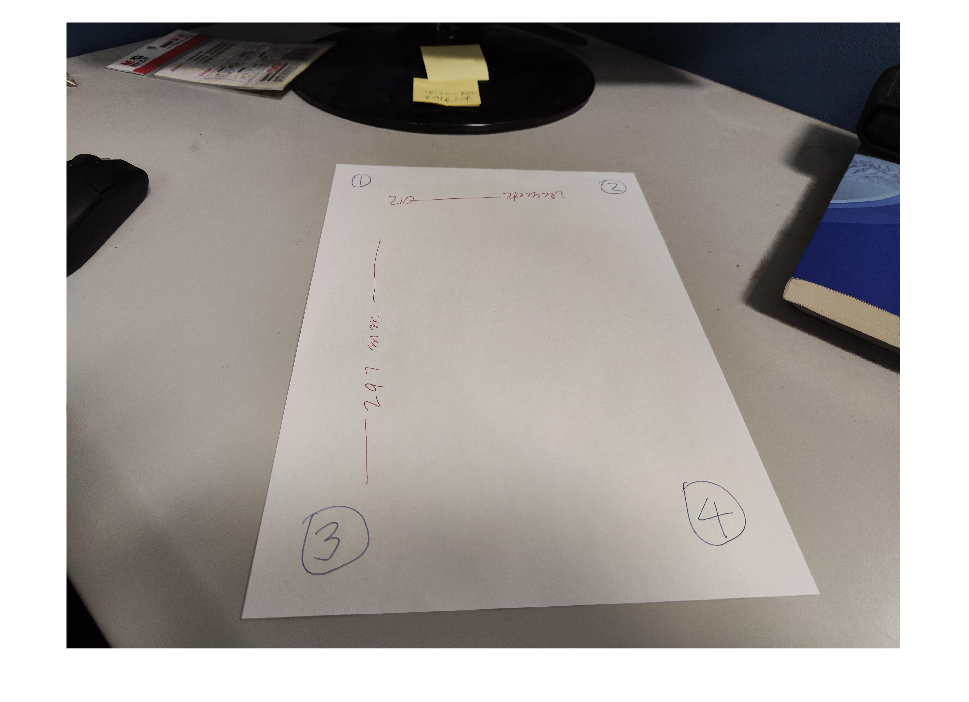


% 显示结果
figure;
imshow(img); title('原始图像');

imshow(corrected_img); title('校正后图像');